Филимонов Степан РЛ6-31

Лабараторная номер 6

Фото задания:

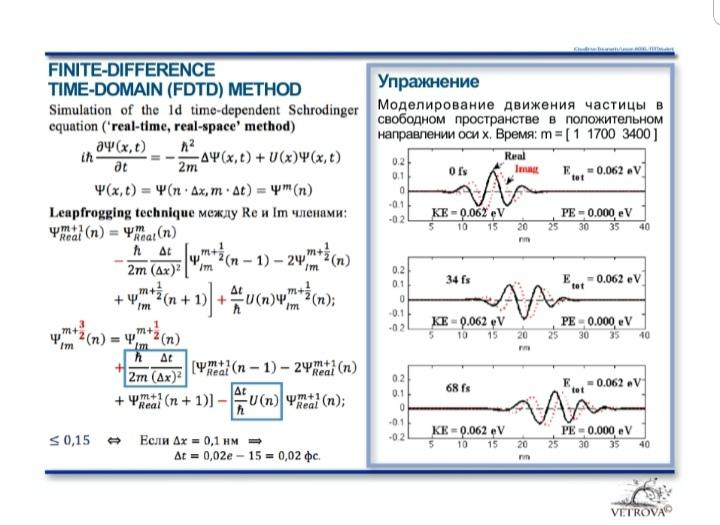

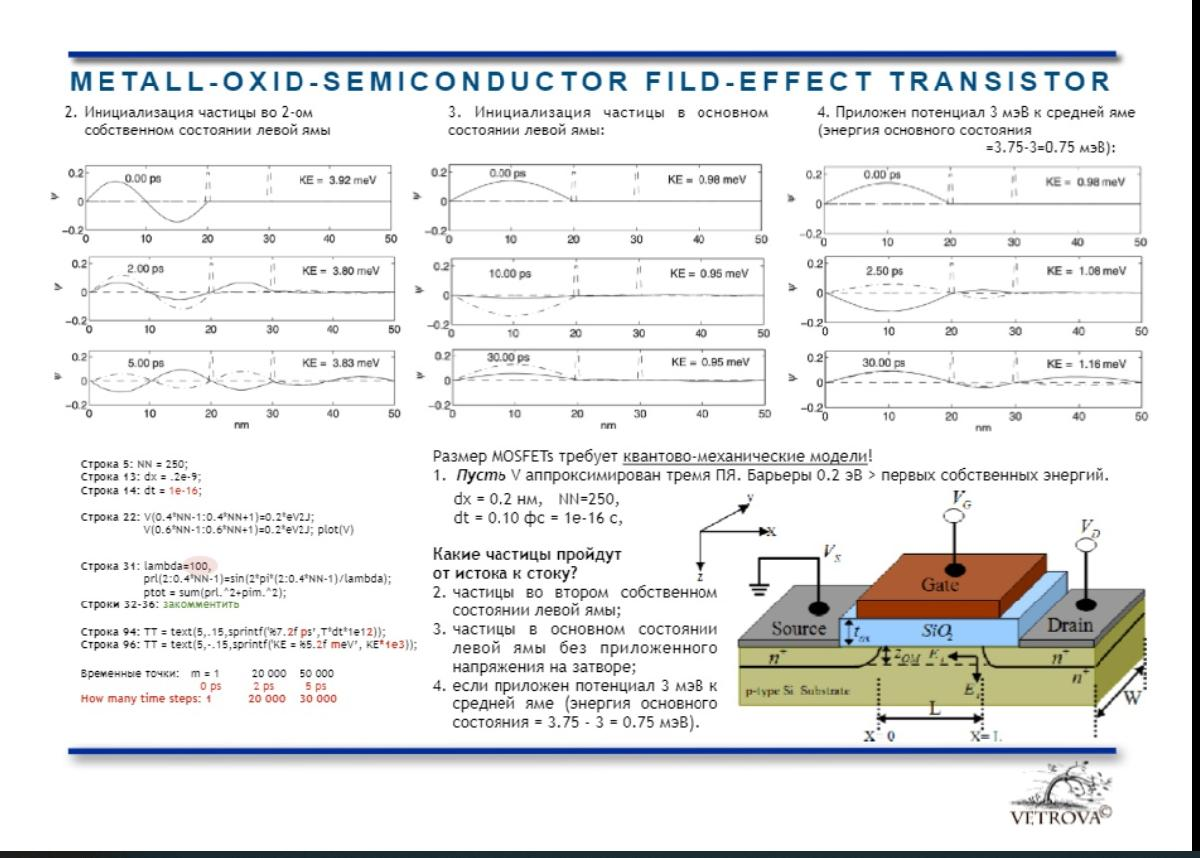

Решение:

***Задание 1:***

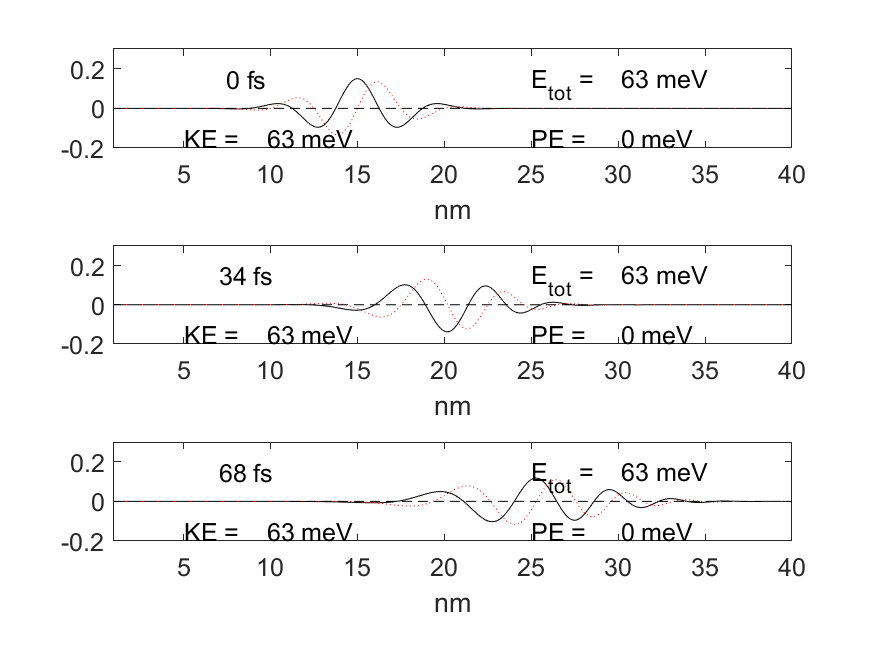

***Задание 2:***

***Затвор закрыт***

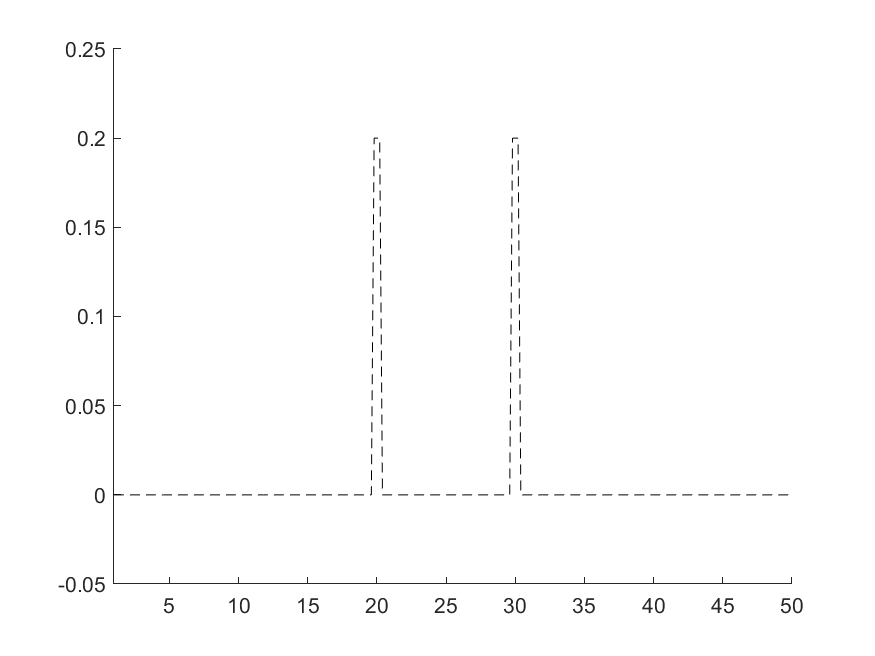

**Инициализация частицы во 2-ом собственном состоянии левой ямы**

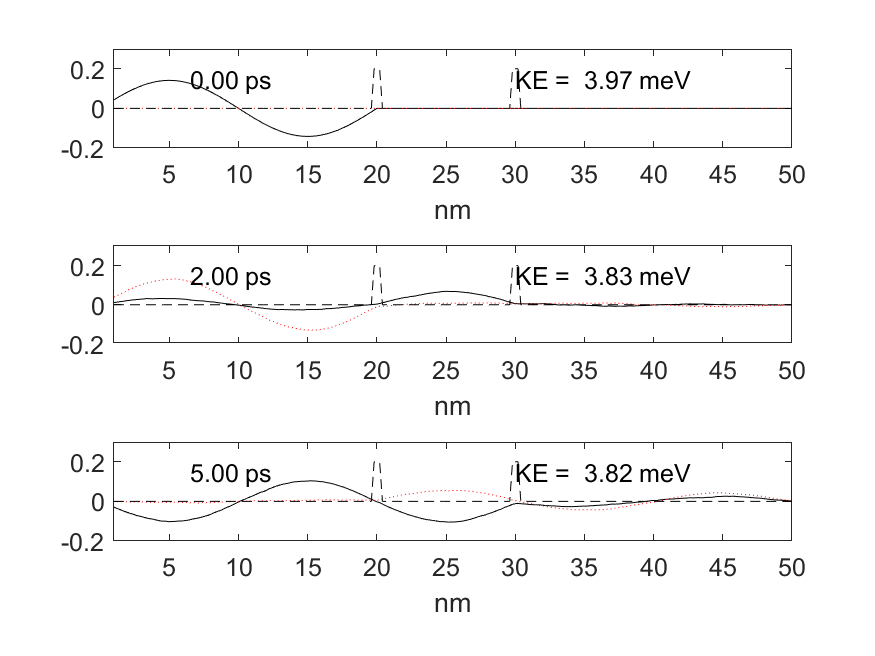

***Задание 3:***

**инициализация частицы в основном состоянии левой ямы**

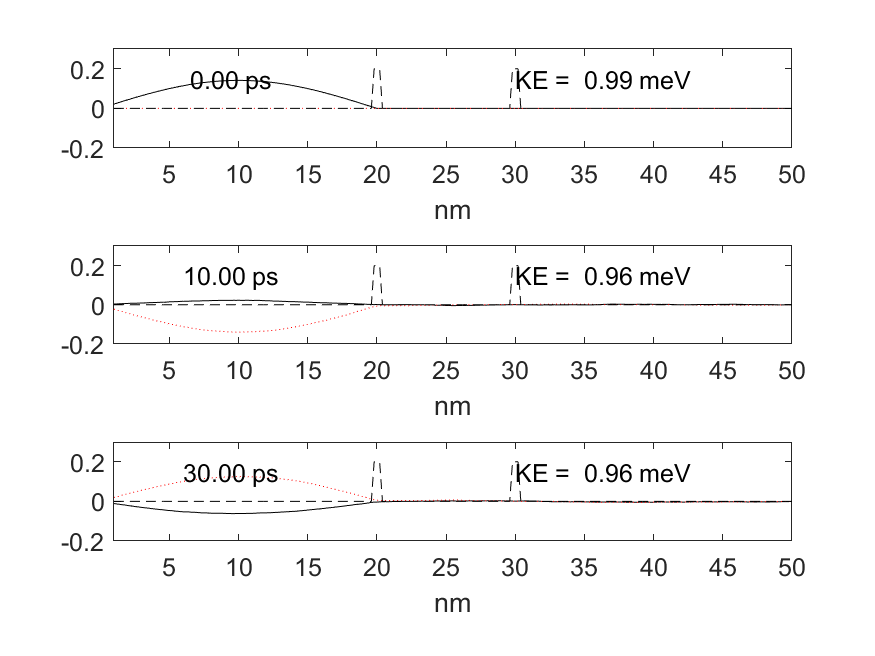

***Задание 4:***

***Затвор открыт***

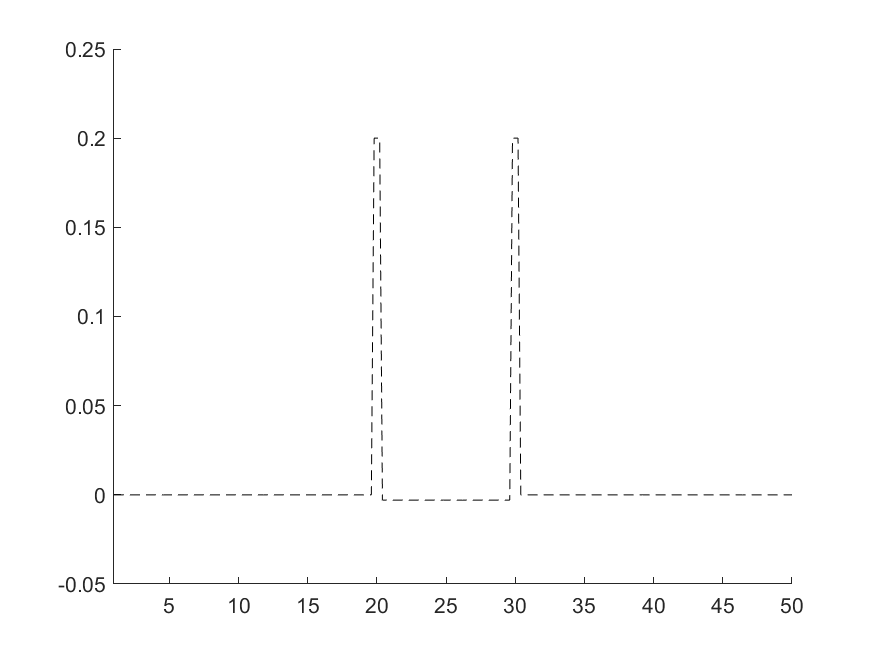

***Приложен потенциал 3 мэВ к средней яме***

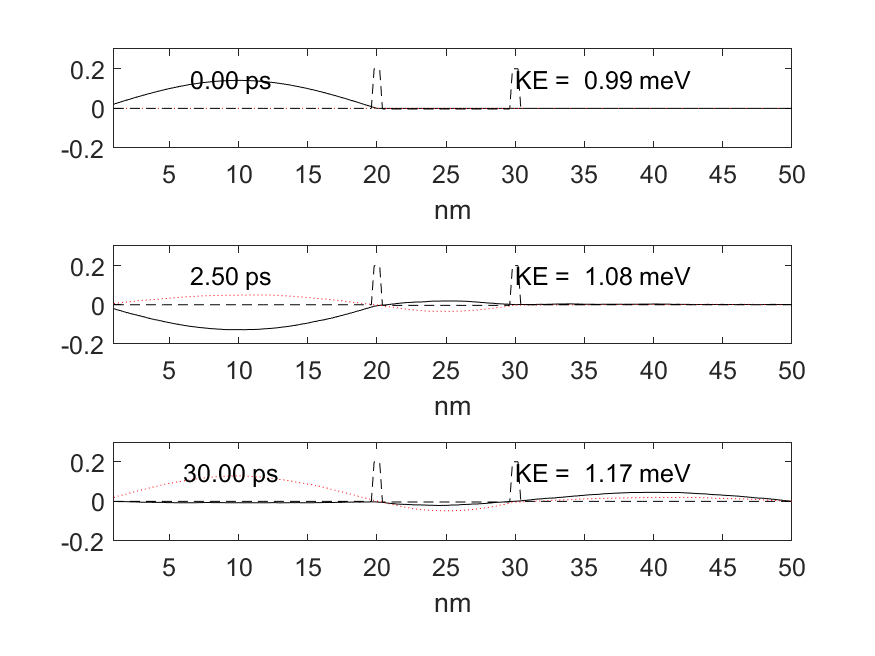

***Тестовое задание:***

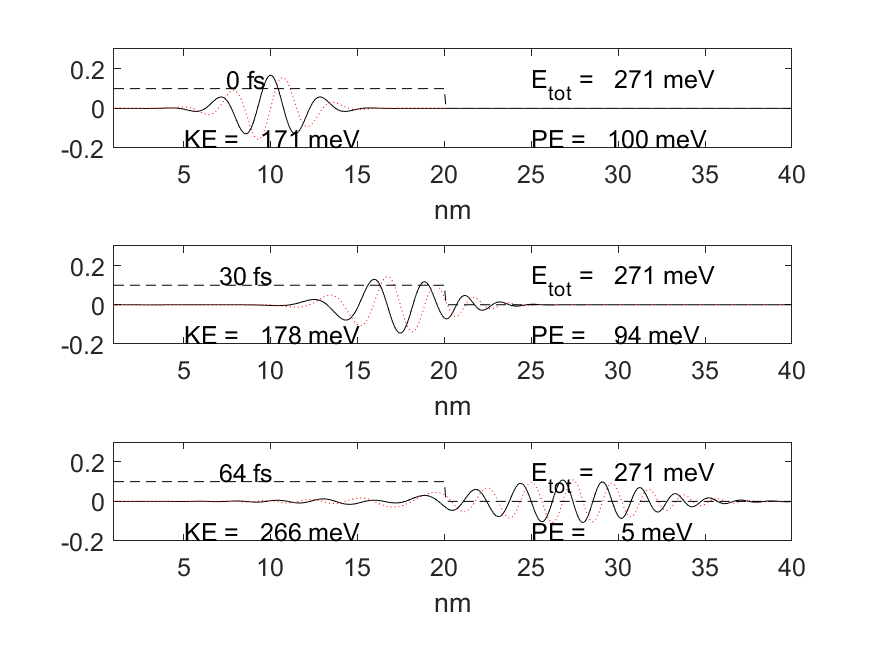

Код Matlab:

cla reset;
hold on;
load("constans.mat");

- **Константы и значения**

i = sqrt(-1);
%Np = 400;  % Количество точек в проблемном пространстве Np = 400;
Np = 250;
T = 0;
Nstep=1;
% time = [1 1699 1700]; % задание 1
% time = [1 19999 30000]; % задние 2
% time = [1 99999 200000]; % задние 3
time = [1 24999 275000]; % задние 4
meff = 1;  % эффективная масс: Si is 1.08, Ge is 0.067, GaAs is 0.55
m = meff * m0;  % Масса электрона
% dx = 0.1e-9; % Размер ячейки dx = 0.1e-9;
dx = 0.2e-9;
% dt = 2e-17; % Временные шаги dt = 0.2e-17;
dt = 1e-16;


$$\textrm{ra}=\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }$$


ra = (hbar / (2 * m)) * (dt /(dx)^2)  % Коэфицент номер 1, должен быть меньше < 0.15

ra = 0.1447

ra < 0.15 -> возможна связь

DX = dx * 1e9;  % Целое колличество нм
XX = (1:Np) * DX; % Длина в нм для построения графика            
Dsquared = (diag(ones(1,Np-1),1) - 2 * diag(ones(1,Np)) + diag(ones(1,Np-1),-1));  % диагональ 1 -2 1

- **Потенциал**

V = zeros(1,Np)'; % 0..- => ' => 0|.. вертикальной сделает
% -------------------------- Задание test -----------------------------------------------------------------
% V = [zeros(1,Np/2) + 0.1 zeros(1,Np/2)]'*eV2J; % половина нули половина eV2J

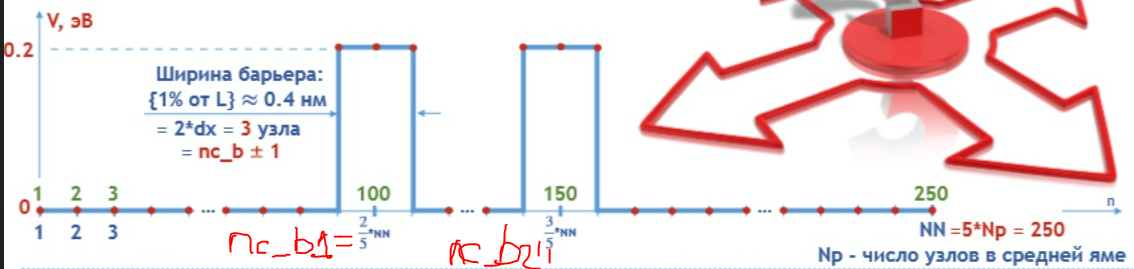

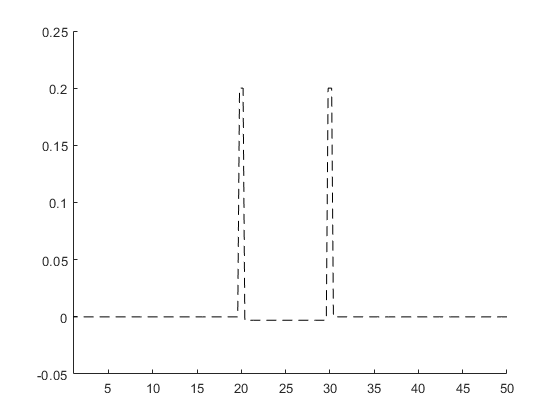

% -------------------------- Задание 2... -----------------------------------------------------------------
nc_b1 = 2/5*Np; 
nc_b2 = 3/5*Np;
% создание барьеров высотой 0.2эВ
V(nc_b1-1:nc_b1+1)=0.2*eV2J;
V(nc_b2-1:nc_b2+1)=0.2*eV2J;
% -------------------------- Задание 4 -----------------------------------------------------------------
% имитация напряжение на затворе
V(nc_b1+2:nc_b2-2)=-0.003*eV2J;
axis([1 DX*Np -0.05 0.25])
plot(XX,J2eV*V,'--k')

% saveas(gcf,'MOSFET_close.png') 

- **Инициализируем синусоидальную волну в гауссовой огибающей**


$$P=e^{-\frac{{\left(n-\textrm{исходное}\;\textrm{положение}\right)}^2 }{2*\textrm{ширина}\;{\textrm{импульса}}^2 }} *\left(\cos \left(2\pi \frac{n-\textrm{исходное}\;\textrm{положение}}{\textrm{длина}\;\textrm{волны}}\right)+i*\sin \left(2\pi \frac{n-\textrm{исходное}\;\textrm{положение}}{\textrm{длина}\;\textrm{волны}}\right)\right)$$


% -------------------------- Задание 1 -----------------------------------------------------------------
% lambda = 50;  % Длина волны импульса % для того чтобы была как в из усл. 50
% lamda_test = lambda * dx * 1e9
% sigma = 25;  % Ширина импульса % для того чтобы была как в из усл. 25 
% nc = 150;  % для того чтобы была как в из усл. 150
% n=(1:Np)';
% Pulse = exp(-0.5*((n-nc)/sigma).^2).*(cos(2*pi*(n-nc)/lambda) + i*sin(2*pi*(n-nc)/lambda));
% PulseReal = real(Pulse); % Реальня часть импульса
% PulseImag = imag(Pulse); % Мнимая часть импульса
% -------------------------- Задание 2 -----------------------------------------------------------------
% lambda = 100;
% PulseReal(2:nc_b1) = sin(2*pi*(2:nc_b1)/lambda);
% PulseReal(nc_b1:Np) = 0;
% PulseImag(1:Np) = 0;
% -------------------------- Задание 3 и 4 -----------------------------------------------------------------
lambda = 200;
PulseReal(2:nc_b1) = sin(2*pi*(2:nc_b1)/lambda);
PulseReal(nc_b1:Np) = 0;
PulseImag(1:Np) = 0;
% -------------------------------------------------------------------------------------------
PulseZ = PulseReal + i * PulseImag; % И мнимая и реальная часть импульса

- **Нормируем её и проверяем**


$$N=\frac{\overrightarrow{n} }{\left|\overrightarrow{n} \right|}$$


PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)));  % Константа нормализации
PulseReal = PulseReal / PulseNormal;
PulseImag = PulseImag / PulseNormal;
PulseZ = PulseReal + i*PulseImag; 
control = sqrt(sum(PulseZ.*conj(PulseZ)));
PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)))  % Константа нормализации

PulseNormal = 1

- **PDTD**

for n_step = 1:3    

- **Главные вычисления**

    for mm=1:time(n_step)
        T = T + 1;
        PulseReal = PulseReal - ra*Dsquared*PulseImag + (dt/hbar)*V.*PulseImag;              

                  
$$\Psi_{\mathrm{Real}} \left(n\right)=\Psi_{\mathrm{Real}}^m \left(n\right)-\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }*\Psi_{\mathrm{Imag}} \left\lbrack \left(n-1\right)-2*\left(n\right)+\left(n+1\right)\right\rbrack \;+\;\frac{\Delta t}{\hbar }U\left(n\right)\Psi_{\mathrm{Imag}} \;$$


        PulseImag = PulseImag + ra*Dsquared*PulseReal - (dt/hbar)*V.*PulseReal;      

                  
$$\Psi_{\mathrm{Imag}} \left(n\right)=\Psi_{\mathrm{Imag}}^m \left(n\right)+\;\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }*\Psi_{\mathrm{Real}} \left\lbrack \left(n-1\right)-2*\left(n\right)+\left(n+1\right)\right\rbrack -\;\frac{\Delta t}{\hbar }U\left(n\right)\Psi_{\mathrm{Real}} \;$$


    end
    subplot(3,1,Nstep)
    plot(XX,real(PulseReal),'k',"Color","black") 
    hold on
    plot(XX,real(PulseImag),':k',"Color","red")
    plot(XX,J2eV*V,'--k') % потенциальная энерги 
    hold off
    axis([1 DX*Np -0.2 0.3])
    xlabel('nm')
    set(gca,'fontsize',12)
    Nstep = Nstep + 1;

- **Подписываем график**

    % ------- Проверяем нормализацию -----------------
    PulseZ = PulseReal+i*PulseImag; 
    PulseZ'*PulseZ 
    PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)));
    % ------- Вычислите ожидаемые значения ------------
    KE = J2eV * real(-(hbar/dx)^2/(2*m)*PulseZ'*(Dsquared*PulseZ))*1e3; % Кинетическая энергия
    PE = J2eV * PulseZ' * (V.*PulseZ)*1e3; % Потенциальная энергия
    TT = text(5,.15,sprintf('%7.2f ps',T*dt*1e12));
    set(TT,'fontsize',12)
    TT = text(30,.15,sprintf('KE = %5.2f meV',KE)); % 5,-.15, кординаты при первом и тестовом задании
    set(TT,'fontsize',12)
% -------------------------- Задание 1 -----------------------------------------------------------------
%     TT = text(25,-.15,sprintf('PE = %5.0f meV',PE));
%     set(TT,'fontsize',12)
%     TT = text(25,.13,sprintf('E_t_o_t = %5.0f meV',KE+PE));
%     set(TT,'fontsize',12)

- **Сохраняем график**

ans = 1.0000

ans = 1.0000

ans = 1.0000

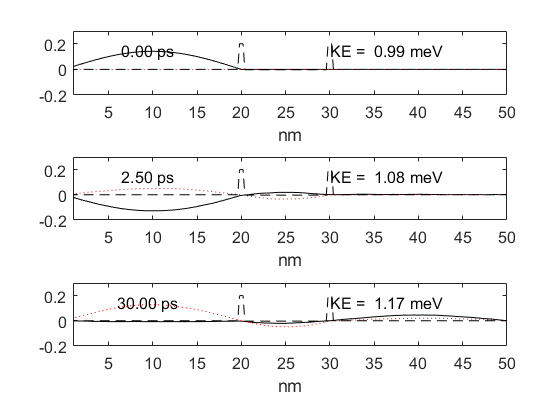

    saveas(gcf,'fourth_task.png')      % This saves the picture to a file
end

- **Время:**

datetime('now')

ans = datetime
   17-Dec-2021 11:27:05
